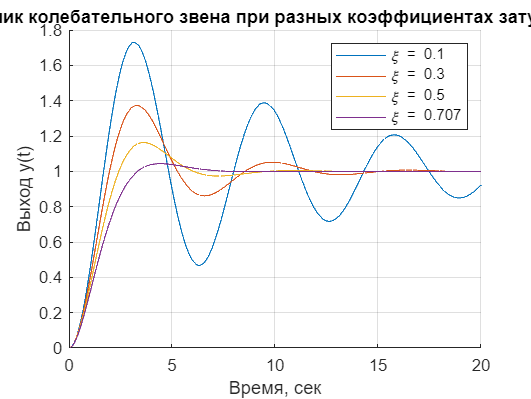

clear all
clc

% Параметры
T = 1;        % постоянная времени
k = 1;        % усиление
xis = [0.1, 0.3, 0.5, 0.707];  % разные коэффициенты демпфирования

% Временная ось
t = 0:0.01:20;

% Единичный вход
u = ones(size(t));

figure;
hold on;

for i = 1:length(xis)
    xi = xis(i);

    % Передаточная функция: W(s) = k / (T^2 s^2 + 2 xi T s + 1)
    num = [k];
    den = [T^2, 2*xi*T, 1];
    sys = tf(num, den);

    % Отклик на ступеньку (единичный вход)
    y = lsim(sys, u, t);

    % Построение
    plot(t, y, 'DisplayName', ['\xi = ' num2str(xi)])
end

% Оформление
xlabel('Время, сек')
ylabel('Выход y(t)')
title('Отклик колебательного звена при разных коэффициентах затухания')
legend show
grid on